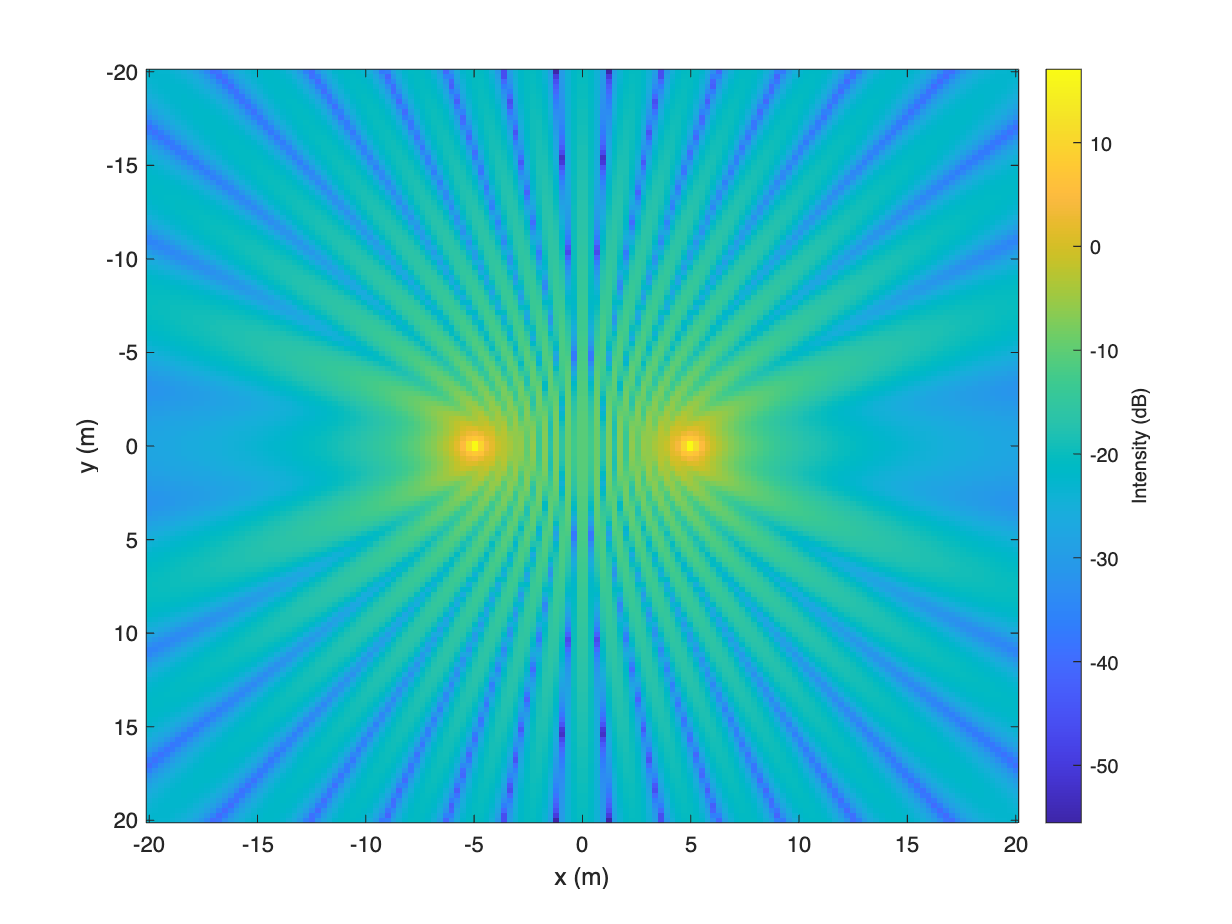

f = 1290; % frequency in Hz
d = 10; % Seperation between sources
c = 1500 ; % Speed of sound (m/s)


dmax = 10;
Lx = 2*dmax;
Ly = 2*dmax;
Nx = 150;
Ny = Nx;
x = linspace(-Lx,Lx,Nx);
y = linspace(-Ly,Ly,Ny);

[X,Y] = meshgrid(x,y);

r1 = sqrt((X - d/2).^2 + Y.^2);
r2 = sqrt((X + d/2).^2 + Y.^2);

SourceState = 1;
if SourceState
    A2 = 1;
else
    A2 = 0;
end

p1 = exp(1i*2*pi*f*r1/c)./r1;
p2 = A2.*exp(1i*2*pi*f*r2/c)./r2;
p = p1 + p2;

plotType = 1;

if plotType == 0
    imagesc(x,y,real(p))
    a = gca;
    a.XLabel.String = 'x (m)';
    a.YLabel.String = 'y (m)';
    c1 = colorbar;
    c1.Label.String = 'Pressure (Pa)';

else
    imagesc(x,y,10*log10(abs(p).^2))
    a = gca;
    a.XLabel.String = 'x (m)';
    a.YLabel.String = 'y (m)';
    c1 = colorbar;
    c1.Label.String = 'Intensity (dB)';
end

Concepts to discuss with this widget:

- Free space propagation

- Constructive interference

- Destructive interference